% Fixed parameters (adjust as needed)
T_total = 100000;                  % Total simulation time (ms)
packet_reception_time = 10;        % Time to receive a packet (ms)
longDRX_cycle = 2560;              % Long DRX cycle (ms)
inactivity_timer = 80;            % Inactivity timer (ms)
on_duration = 80;                 % On duration (ms)

% Vary shortCycleTimer (for the first plot)
shortDRX_cycle_fixed = 512;        % Fixed short DRX cycle (ms)
shortCycleTimer_values = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16];    % Range of shortCycleTimer values

% Tested packet frequencies (ms)
packet_frequencies = [250, 500, 1000, 2000, 5000];

% Preallocate results
energy_gains = zeros(length(packet_frequencies), length(shortCycleTimer_values));
mean_delays = zeros(length(packet_frequencies), length(shortCycleTimer_values));

% Simulate for each packet frequency
for freq_idx = 1:length(packet_frequencies)
    frequency_of_incoming_packet = packet_frequencies(freq_idx);
    
    for i = 1:length(shortCycleTimer_values)
        [energy_gains(freq_idx, i), mean_delays(freq_idx, i)] = c_drx_script(...
            T_total, longDRX_cycle, inactivity_timer, on_duration, ...
            frequency_of_incoming_packet, packet_reception_time, ...
            shortDRX_cycle_fixed, shortCycleTimer_values(i));
    end
end


=== Starting C-DRX Simulation ===
Total simulation time: 100000 ms
Long DRX cycle: 2560 ms
Short DRX cycle: 512 ms
Short DRX cycle timer: 1
Inactivity timer: 80 ms
On duration: 80 ms
Packet frequency: 250 ms
Packet reception time: 10 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 80 ms (Energy: 8000.0 mJ)
! STATE ON time counter: 80)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
DEEP_SLEEP: 432 ms (Energy: 671.3 mJ)
[Energy update] Total: 8671.3 mJ | Saved: 0.1%
short_DRX_counter: 512
Short DRX Timer short cycle zostało: 0
short_DRX_counter: 512
reszta po shortDRXie: 512
-> State change: SLEEP -> ON_DURATION

[Packet #3 arrived during SLEEP at last cycle at 250 ms]

[Processing 2 pending packets that arrived during SLEEP]
-> Processing packet arrived at 250 ms (delay: 262 ms)
-> Processing packet arrived at 500 ms (delay: 12 ms)
[Energy after processing 2 packets] Total: 20671.3 mJ | Saved: 0.2%
-> State change: ON_DURATION -> INACTIVITY_TIMER (Cycle #2)
INACTIVITY_TIME

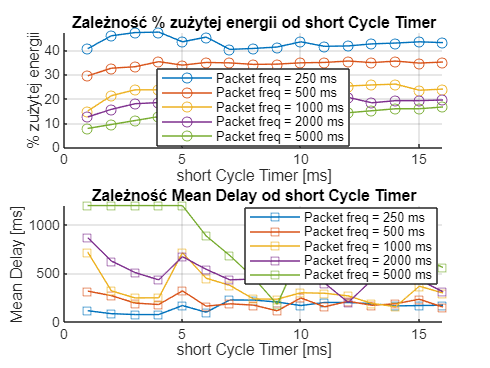


% Plot results
figure;

% Energy Gain vs. shortCycleTimer
subplot(2, 1, 1);
hold on;
colors = lines(length(packet_frequencies));
for freq_idx = 1:length(packet_frequencies)
    plot(shortCycleTimer_values, energy_gains(freq_idx, :), '-o', ...
        'Color', colors(freq_idx, :), ...
        'DisplayName', sprintf('Packet freq = %d ms', packet_frequencies(freq_idx)));
end
hold off;
title('Zależność % zużytej energii od short Cycle Timer');
xlabel('short Cycle Timer [ms]');
ylabel('% zużytej energii');
legend('Location', 'best');
grid on;

% Mean Delay vs. shortCycleTimer
subplot(2, 1, 2);
hold on;
for freq_idx = 1:length(packet_frequencies)
    plot(shortCycleTimer_values, mean_delays(freq_idx, :), '-s', ...
        'Color', colors(freq_idx, :), ...
        'DisplayName', sprintf('Packet freq = %d ms', packet_frequencies(freq_idx)));
end
hold off;
title('Zależność Mean Delay od short Cycle Timer');
xlabel('short Cycle Timer [ms]');
ylabel('Mean Delay [ms]');
legend('Location', 'best');
grid on;

% Fixed parameters
T_total = 100000;                  % Total simulation time (ms) miedzy 50-80k
longDRX_cycle = 2560;              % Long DRX cycle (ms)
inactivity_timer = 10;             % Inactivity timer (ms)
on_duration = 10;                  % On duration (ms)
packet_reception_time = 10;        % Time to receive a packet (ms)
shortCycleTimer_fixed = 5;         % Fixed shortCycleTimer value

% Tested packet frequencies (ms)
packet_frequencies = [250, 500, 1000, 2000, 5000];

% Range of short DRX cycle values (ms)
shortDRX_cycle_values = [16, 20, 32, 40, 64, 80, 128, 160, 256, 320, 512, 640];

% Preallocate results
energy_gains = zeros(length(packet_frequencies), length(shortDRX_cycle_values));
mean_delays = zeros(length(packet_frequencies), length(shortDRX_cycle_values));

% Simulate for each packet frequency
for freq_idx = 1:length(packet_frequencies)
    frequency_of_incoming_packet = packet_frequencies(freq_idx);
    
    for i = 1:length(shortDRX_cycle_values)
        [energy_gains(freq_idx, i), mean_delays(freq_idx, i)] = c_drx_script(...
            T_total, longDRX_cycle, inactivity_timer, on_duration, ...
            frequency_of_incoming_packet, packet_reception_time, ...
            shortDRX_cycle_values(i), shortCycleTimer_fixed);
    end
end


=== Starting C-DRX Simulation ===
Total simulation time: 100000 ms
Long DRX cycle: 2560 ms
Short DRX cycle: 16 ms
Short DRX cycle timer: 5
Inactivity timer: 10 ms
On duration: 10 ms
Packet frequency: 250 ms
Packet reception time: 10 ms

Initial state: inactivity_timer
INACTIVITY_TIMER: 10 ms (Energy: 1000.0 mJ)
! STATE ON time counter: 10)
-> State change: INACTIVITY_TIMER -> SLEEP (Cycle #1)
LIGHT_SLEEP: 6 ms (Energy: 130.6 mJ)
[Energy update] Total: 1130.6 mJ | Saved: 0.0%
short_DRX_counter: 16
Short DRX Timer short cycle zostało: 4
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 10
ON_DURATION: 10 ms (Energy: 1000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle #2)
LIGHT_SLEEP: 6 ms (Energy: 130.6 mJ)
[Energy update] Total: 2261.3 mJ | Saved: 0.0%
short_DRX_counter: 32
Short DRX Timer short cycle zostało: 3
-> State change: SLEEP -> ON_DURATION
! STATE ON time counter: 10
ON_DURATION: 10 ms (Energy: 1000.0 mJ)
-> State change: ON_DURATION -> SLEEP (Cycle #3)
LIGHT

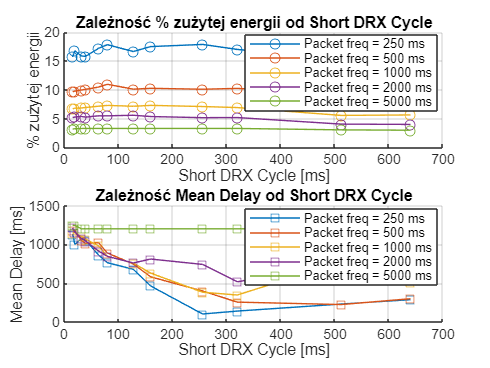


% Plot results
figure;

% Energy Gain vs. Short DRX Cycle
subplot(2, 1, 1);
hold on;
colors = lines(length(packet_frequencies));
for freq_idx = 1:length(packet_frequencies)
    plot(shortDRX_cycle_values, energy_gains(freq_idx, :), '-o', ...
        'Color', colors(freq_idx, :), ...
        'DisplayName', sprintf('Packet freq = %d ms', packet_frequencies(freq_idx)));
end
hold off;
title('Zależność % zużytej energii od Short DRX Cycle');
xlabel('Short DRX Cycle [ms]');
ylabel('% zużytej energii');
legend('Location', 'best');
grid on;

% Mean Delay vs. Short DRX Cycle
subplot(2, 1, 2);
hold on;
for freq_idx = 1:length(packet_frequencies)
    plot(shortDRX_cycle_values, mean_delays(freq_idx, :), '-s', ...
        'Color', colors(freq_idx, :), ...
        'DisplayName', sprintf('Packet freq = %d ms', packet_frequencies(freq_idx)));
end
hold off;
title('Zależność Mean Delay od Short DRX Cycle');
xlabel('Short DRX Cycle [ms]');
ylabel('Mean Delay [ms]');
legend('Location', 'best');
grid on;